% SHAPC-Mean and SHAPC-Var Comparison
algs = ["iTAML", "RPSnet", "DGR", "foster", "memo", ...
     "der", "icarl", "ds-al", "tagfex", "xder"];
dataset = 'cifar100';

if dataset == "cifar100"
    num_sessions = 10;
    cls_per_task = 10;
else
    num_sessions = 5;
    cls_per_task = 2;
end

if dataset ~= "mnist"
    algs(algs=="DGR") = [];
end
num_algs = length(algs);

file_path = sprintf("%s_all_inclass_shapcs.mat", dataset);
if isfile(file_path)
    all_inclass_shapcs = load(file_path).all_inclass_shapcs;
else
    all_inclass_shapcs = zeros(((num_sessions-1)*cls_per_task), num_algs+1);
end

for j=1:length(algs)
    alg = algs(j);
    % Load SHAPC values (First and Last 1000)
    save_path = sprintf("%s/%s/shapc_vals_inclass.mat", alg, dataset);
    if isfile(save_path)
        inclass_struct = load(save_path);
    
        for i=1:((num_sessions-1)*cls_per_task)
            cls = i - 1;
    
            cls_str = sprintf("cls%d", cls);
            shapc_struct = inclass_struct.(cls_str);
           
            % Load SHAPC values all
            shapc_avgs = [];
            pair_str = 'sc' + string(floor(cls/cls_per_task)) + string(num_sessions-1);
            shapcs = [];
            sample_list = string(fieldnames(shapc_struct.(pair_str)));
            for k=1:length(fieldnames(shapc_struct.(pair_str)))
                sample_str = sample_list(k);%'sample' + string(k-1);
                shapcs = [shapcs; shapc_struct.(pair_str).(sample_str)];
            end
            shapc_avgs = [shapc_avgs; mean(shapcs)];
            
            % Note the shapc is represented as percentage
            %disp("From averaging all tasks together:")
            shapc_mean_perc = mean(shapc_avgs);
            shapc_mean = mean(shapc_avgs) / 100;
                        
            if ~exist('inclass_shapcs','var')
                inclass_shapcs = zeros(((num_sessions-1)*cls_per_task),2);
            end
            
            inclass_shapcs(cls+1,1) = cls;
            inclass_shapcs(cls+1,2) = shapc_mean_perc;
        end
        all_inclass_shapcs(:, find(algs==alg)+1) = inclass_shapcs(:,2);
    end
    save(file_path, "all_inclass_shapcs")
end

% Display All Results
fprintf('Inclass SHAPC-Mean Percentages:\n');

Inclass SHAPC-Mean Percentages:


disp(inclass_shapcs);

         0   25.2286
    1.0000   22.3682
    2.0000   24.0126
    3.0000   22.8252
    4.0000   22.8374
    5.0000   23.7362
    6.0000   23.4771
    7.0000   23.8377
    8.0000   24.1881
    9.0000   23.4208
   10.0000   23.2593
   11.0000   24.3000
   12.0000   23.5922
   13.0000   23.4834
   14.0000   23.6269
   15.0000   23.4888
   16.0000   24.4148
   17.0000   24.5711
   18.0000   22.7099
   19.0000   23.6193
   20.0000   26.2828
   21.0000   24.6301
   22.0000   23.9275
   23.0000   25.4470
   24.0000   24.3610
   25.0000   23.8135
   26.0000   22.8645
   27.0000   22.4721
   28.0000   24.3984
   29.0000   22.9640
   30.0000   25.5081
   31.0000   24.9077
   32.0000   22.9506
   33.0000   25.2516
   34.0000   23.7745
   35.0000   27.0131
   36.0000   24.9774
   37.0000   24.0101
   38.0000   23.3504
   39.0000   24.7316
   40.0000   24.9750
   41.0000   25.9783
   42.0000   25.2144
   43.0000   26.6820
   44.0000   23.5165
   45.0000   24.4148
   46.0000   26.8998
   47.0000   


fprintf('Std Dev:\n');

Std Dev:


disp(std(inclass_shapcs(:,2)))

    4.2690




fprintf('Avg:\n');

Avg:


disp(mean(inclass_shapcs(:,2)))

   27.2181



create_table = true;
if create_table
    if ~exist('inclass_shapcs','var')
        all_inclass_shapcs = load(file_path).all_inclass_shapcs;
    end

    % Create a table for better visualization of results
    all_inclass_shapcs(:, 1) = (1:(num_sessions-1)*cls_per_task)-1;
    resultsTable = array2table(all_inclass_shapcs, 'VariableNames', ['Class' algs]);
    disp(resultsTable);

    all_std_devs = [NaN std(all_inclass_shapcs(:, 2:end))];
    fprintf('Std Devs:\n');
    disp(all_std_devs);

    all_avgs = [NaN mean(all_inclass_shapcs(:, 2:end))];
    fprintf('Averages:\n');
    disp(all_avgs);
end

    Class    iTAML     RPSnet    foster     memo      der      icarl     ds-al    tagfex    xder
    _____    ______    ______    ______    ______    ______    ______    _____    ______    ____

      0      23.953    27.571     26.88    25.802      32.7    25.229      0        0        0  
      1      25.983    23.985    26.719    24.582    32.547    22.368      0        0        0  
      2       24.27    24.637    25.505    23.566    28.301    24.013      0        0        0  
      3      22.692    22.978    24.142    22.605    25.132    22.825      0        0        0  
      4      23.086    22.528    26.404    23.009    24.692    22.837      0 

Std Devs:


       NaN    2.8994    8.2129    2.8379    4.5576    8.3585    4.2690         0         0         0



Averages:


       NaN   27.2600   30.7623   28.7740   31.2215   41.4523   27.2181         0         0         0




% Cls 7 has the highest SHAPCs for all algs
% Except for foster -> Cls 8

% Cls 1 has the lowest SHAPCs for all algs
% Except for RPSnet -> Cls 4

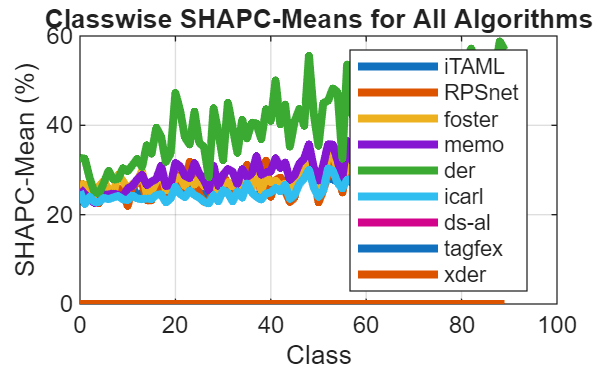

% Plot inclass shapcs

plot((all_inclass_shapcs(:, 1)), ...
    (all_inclass_shapcs(:, 2:end)), ...
    'LineWidth', 3)
title('Classwise SHAPC-Means for All Algorithms');
xlabel('Class');
ylabel('SHAPC-Mean (%)');
legend(algs,"Location", "best")
grid on;